This document will serve as a reference for running data, in this case the turbulent data.

Add our paths to our dependency

addpath('plotting_camera');
addpath('ptvcodes');

Generate a new working folder 

% Name of our new working folder 
new_name = 'JHU_02';
if exist(new_name)
    disp('Folder exist')
else
    % make that folder 
    mkdir new_name;
    % copy default contents into our new working folder 
    copyfile('JHU',new_name);
end

Specify our working folder

% Working folder
work_dir = new_name;

## Calibration Images

        To generate calibration images we first need to specify the calibration directory:

% Working calibration folder 
cal_dir = [work_dir,'/cal'];

Then we can generate the calibration images using: 

calTargetMultiView('save',true,'cal_dir',cal_dir,'TargetFile', true,'target_3D',true,'generate_ori', true)

## Flow Images:

    To generate images of the particle postions, we need to specify the image directory and ensure that the folder is empty. This code will specify said directory, and if it exist already, it will remove it.

img_dir  = [work_dir,'/img'];
if exist(img_dir)
% Remove the exiting img folder
    disp('exist')
    rmdir(img_dir,'s')
    disp('Removed image directory')
end

We need data to pass to the makeImageUniversal function

The data must be in a structure with fields,x,y,z. 

where x,y,z are matrics, with points in the rows, and time in the columns

load('JHU_data_four_SIG.mat')

Then we can, generate the images using:

makeImages_universal('outdir',img_dir,'save',true,'plot',true,'data',JHU);

% Remove the tif 
remove_tif_M(img_dir);

test=['C:\Users\alex\Desktop\og\PTV_SYN\',work_dir,'\res'];
% test='C:\Users\alex\Desktop\og\PTV_SYN\test\Copy_of_res';
start = 10001;
last = 10075;
dt=1/100;
min_len = 5;
%------

% main = 'C:\Users\alex\OneDrive - Knights - University of Central Florida\Documents\research_xray\CODE_MAIN\TEST DATA FOR PTV\';
% folder = fullfile(main,test,'res0');

traj_RC=ptv_is_to_traj(test,start,last,min_len,dt);

Reading ...
Done .
Building trajectories
Done
PTV to Traj


plot_long_trajectories(traj_RC,min_len);
v = [10 -8 2];
[caz,cel] = view(v)

caz = 51.3402

cel = 8.8764

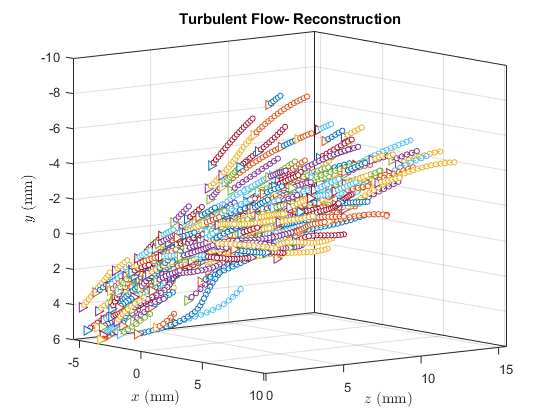

title('Turbulent Flow- Reconstruction')

traj_GT = pos_to_traj(JHU.x,JHU.y,JHU.z,dt);

traj = struct with fields:
        xf: []
        yf: []
        zf: []
        uf: []
        vf: []
        wf: []
       axf: []
       ayf: []
       azf: []
         t: []
    trajid: []


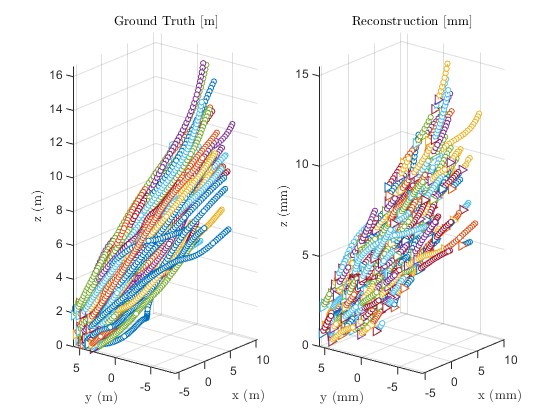

caz = -51.3402

cel = 8.8764

caz = -51.3402

cel = 8.8764

traj_GT = scale_traj(traj_GT,1000);
plot_long_traject_COP(traj_GT,'Ground Truth [m]',traj_RC,'Reconstruction [mm]',min_len)

save('traj_GT_6_1.mat','traj_GT')
save('traj_RC_6_1.mat','traj_RC')